clear all
close all

fileName = '(N100to100_NINPS7to7_N_AL4to20_g0.05to0.05_rGGin5to5_rGinGb999to999_Delay0.01to0.01_DNI0.2to0.2_SNI0.4to0.4_TH0.5to0.5)';
TN = readtable(['Seq_TICycle',fileName, '.csv'], 'ReadRowNames',true, 'NumHeaderLines',0,"Delimiter",' ',"EmptyValue",nan);
TN = array2table(table2array(TN)', 'VariableNames',TN.Row)

TN = 5×10 table
    nInp     g      rGGin    rGinGb    Delay    N_AL    DNI    SNI    TH      N 
    ____    ____    _____    ______    _____    ____    ___    ___    ___    ___

      7     0.05       5      999      0.01       4     0.2    0.4    0.5    100
    NaN      NaN     NaN      NaN       NaN       8     NaN    NaN    NaN    NaN
    NaN      NaN     NaN      NaN       NaN      12     NaN    NaN    NaN    NaN
    NaN      NaN     NaN      NaN       NaN      16     NaN    NaN    NaN    NaN
    NaN      NaN     NaN      NaN       NaN      20     NaN    NaN    NaN    NaN


T = readtable(['TICycle', fileName, '.csv'])

T = 5×125 table
    nInp     g      rGGin    rGinGb    Delay    N_AL    DNI    SNI    TH      N     MeanANC1    StdANC1     MeanANC2    StdANC2     MeanANC3    StdANC3     MeanANC4    StdANC4     MeanANC5    StdANC5     MeanANC6    StdANC6     MeanANC7    StdANC7      MeanA       StdA      SuccA    MeanASD1    StdASD1     SuccASD1    MeanASD2    StdASD2     SuccASD2    MeanASD3    StdASD3     S


M = 50;

voc = 'A':'Z';
hue = flip(brewermap(10, 'Greens'));
hue = flip(hue(1:6,:));

SaveFigures = false;


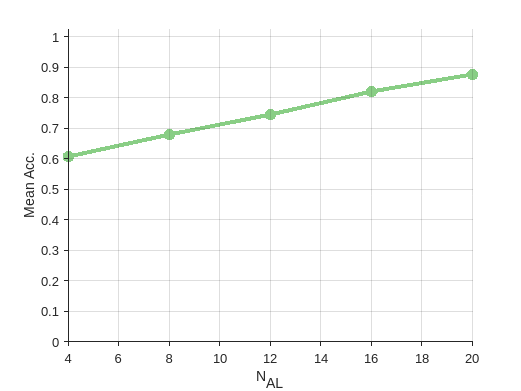

SNI = 0.4;

figure
hold on

condition1 = (T.SNI == SNI);
ndx = find(condition1);
errorbar(T.N_AL(ndx), T.MeanA(ndx), T.StdA(ndx)/sqrt(90), "Color", hue(1,:), ...
"LineStyle","-", "LineWidth",3,"Marker",".","MarkerSize",30)

ylim([0 1.025])
xlabel('N_{AL}')
ylabel('Mean Acc.')
set(gca,'Layer','top','TickDir','out','Box','off')

grid on

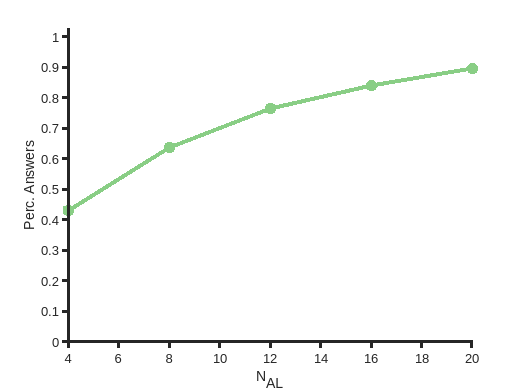

figure

errorbar(T.N_AL, T.PercAnsw, T.StdPA/sqrt(M), "Color", hue(1,:), ...
"LineStyle","-", "LineWidth",3,"Marker",".","MarkerSize",30)

ylim([0 1.025])
xlabel('N_{AL}')
ylabel('Perc. Answers')
set(gca,'Layer','top','TickDir','out','Box','off')

grid off
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')



if SaveFigures
    hgexport(gcf,'PercAnsw');
end

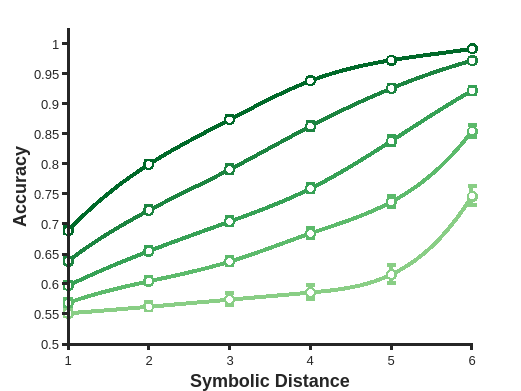

SNI = 0.4;

figure
hold on
for k = 1:numel(TN.N_AL)
    condition1 = (T.N_AL == TN.N_AL(k)) & (T.SNI == SNI);
    
    ndx = find(condition1);
    acc = nan(1,6);
    acc(1) = T.MeanASD1(ndx);
    acc(2) = T.MeanASD2(ndx);
    acc(3) = T.MeanASD3(ndx);
    acc(4) = T.MeanASD4(ndx);
    acc(5) = T.MeanASD5(ndx);
    acc(6) = T.MeanASD6(ndx);
    
    stdAcc = nan(1,6);
    stdAcc(1) = T.StdASD1(ndx);
    stdAcc(2) = T.StdASD2(ndx);
    stdAcc(3) = T.StdASD3(ndx);
    stdAcc(4) = T.StdASD4(ndx);
    stdAcc(5) = T.StdASD5(ndx);
    stdAcc(6) = T.StdASD6(ndx);

    f = griddedInterpolant(1:6,acc,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:6, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"N_{AL}="+TN.N_AL(k))
    plot(1:6, acc,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
end

xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
ylim([0.5 1.025])

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'acc');
end

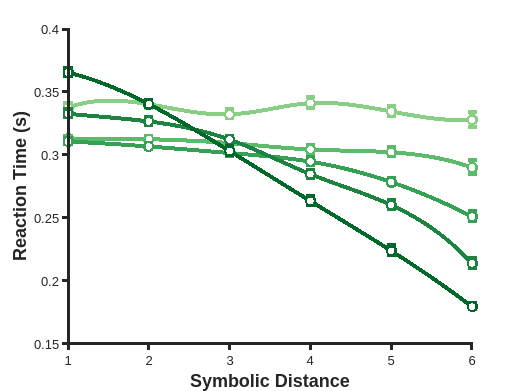

SNI = 0.4;

figure
hold on
for k = 1:numel(TN.N_AL)
    condition1 = (T.N_AL == TN.N_AL(k)) & (T.SNI == SNI);
    ndx = find(condition1);
    reactTimes = nan(1,6);
    reactTimes(1) = T.ReactTimesSD1(ndx);
    reactTimes(2) = T.ReactTimesSD2(ndx);
    reactTimes(3) = T.ReactTimesSD3(ndx);
    reactTimes(4) = T.ReactTimesSD4(ndx);
    reactTimes(5) = T.ReactTimesSD5(ndx);
    reactTimes(6) = T.ReactTimesSD6(ndx);
    
    stdRT = nan(1,6);
    stdRT(1) = T.StdRT1(ndx);
    stdRT(2) = T.StdRT2(ndx);
    stdRT(3) = T.StdRT3(ndx);
    stdRT(4) = T.StdRT4(ndx);
    stdRT(5) = T.StdRT5(ndx);
    stdRT(6) = T.StdRT6(ndx);

    f = griddedInterpolant(1:6,reactTimes,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
  
    errorbar(1:6, reactTimes, stdRT/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"N_{AL}="+TN.N_AL(k))
    plot(1:6, reactTimes,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       

end

xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Time (s)',"FontWeight","bold","FontSize",14)

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'rt');
end

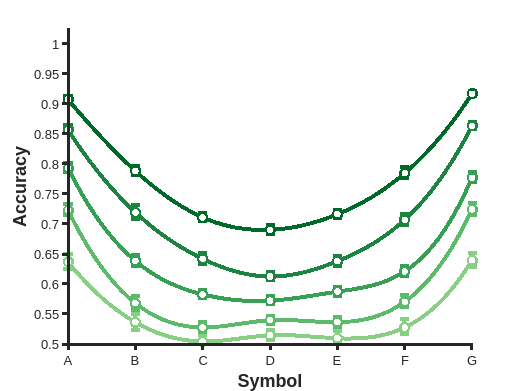

figure
hold on

for k = 1:numel(TN.N_AL)
    condition1 = (T.N_AL == TN.N_AL(k)) & (T.SNI == SNI);
    ndx = find(condition1);
    anc = nan(1,7);
    anc(1) = T.MeanANC1(ndx);
    anc(2) = T.MeanANC2(ndx);
    anc(3) = T.MeanANC3(ndx);
    anc(4) = T.MeanANC4(ndx);
    anc(5) = T.MeanANC5(ndx);
    anc(6) = T.MeanANC6(ndx);
    anc(7) = T.MeanANC7(ndx);
    
    stdAnc = nan(1,7);
    stdAnc(1) = T.StdANC1(ndx);
    stdAnc(2) = T.StdANC2(ndx);
    stdAnc(3) = T.StdANC3(ndx);
    stdAnc(4) = T.StdANC4(ndx);
    stdAnc(5) = T.StdANC5(ndx);
    stdAnc(6) = T.StdANC6(ndx);
    stdAnc(7) = T.StdANC7(ndx);
    
    f = griddedInterpolant(1:7,anc,'spline');
    x = 1:0.1:7;
    plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:7, anc, stdAnc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"N_{AL}="+TN.N_AL(k))
    plot(1:7, anc,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
end

xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
ylim([0.5 1.025])

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'anc');
end

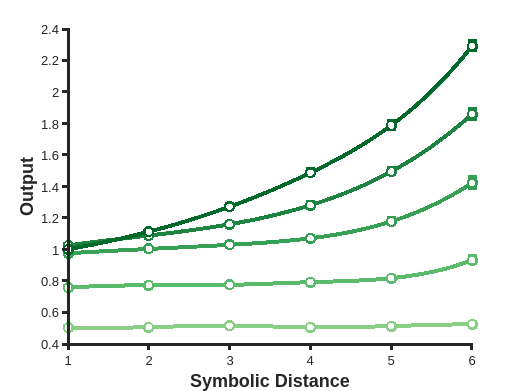

figure
hold on

for k = 1:numel(TN.N_AL)
    condition1 = (T.N_AL == TN.N_AL(k)) & (T.SNI == SNI);
    ndx = find(condition1);
    out = nan(1,6);
    out(1) = T.MaxOutSD1(ndx);
    out(2) = T.MaxOutSD2(ndx);
    out(3) = T.MaxOutSD3(ndx);
    out(4) = T.MaxOutSD4(ndx);
    out(5) = T.MaxOutSD5(ndx);
    out(6) = T.MaxOutSD6(ndx);

    stdOut = nan(1,6);
    stdOut(1) = T.StdMO1(ndx);
    stdOut(2) = T.StdMO2(ndx);
    stdOut(3) = T.StdMO3(ndx);
    stdOut(4) = T.StdMO4(ndx);
    stdOut(5) = T.StdMO5(ndx);
    stdOut(6) = T.StdMO6(ndx);
    
    f = griddedInterpolant(1:6,out,'spline');
    x = 1:0.1:6;
    plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
    
    errorbar(1:6, out, stdOut/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", hue(k,:), 'DisplayName',"N_{AL}="+TN.N_AL(k))
    plot(1:6, out,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")       
end

xticks(1:6)
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Output',"FontWeight","bold","FontSize",14)

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'out');
end

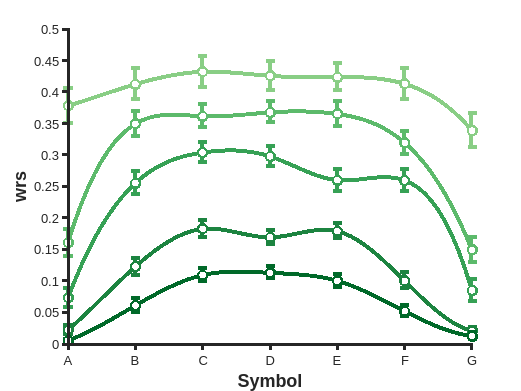

SNI = 0.4;
voc = 'A':'Z';
figure
hold on
for k = 1:numel(TN.N_AL)
    condition1 = (T.N_AL == TN.N_AL(k)) & (T.SNI == SNI);

    ndx = find(condition1);
    wrs = nan(1,7);
    wrs(1) = T.Wrs1(ndx);
    wrs(2) = T.Wrs2(ndx);
    wrs(3) = T.Wrs3(ndx);
    wrs(4) = T.Wrs4(ndx);
    wrs(5) = T.Wrs5(ndx);
    wrs(6) = T.Wrs6(ndx);
    wrs(7) = T.Wrs7(ndx);
    
    stdWrs = nan(1,7);
    stdWrs(1) = T.StdW1(ndx);
    stdWrs(2) = T.StdW2(ndx);
    stdWrs(3) = T.StdW3(ndx);
    stdWrs(4) = T.StdW4(ndx);
    stdWrs(5) = T.StdW5(ndx);
    stdWrs(6) = T.StdW6(ndx);
    stdWrs(7) = T.StdW7(ndx);

    f = griddedInterpolant(1:7,wrs,'spline');
    x = 1:0.1:7;
    plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")

    errorbar(1:7, wrs, stdWrs/sqrt(M),"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 30, "Color", hue(k,:))
    plot(1:7, wrs,"LineStyle","none", "LineWidth", 3,...
        "Marker", ".", "MarkerSize", 12, "Color", 'w')    
end

%legend("Location","best","Box","off")
%xticks(1:8)
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('wrs',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])

%%title("g="+(G) +", g_{b}="+(G/5 /GinGback))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

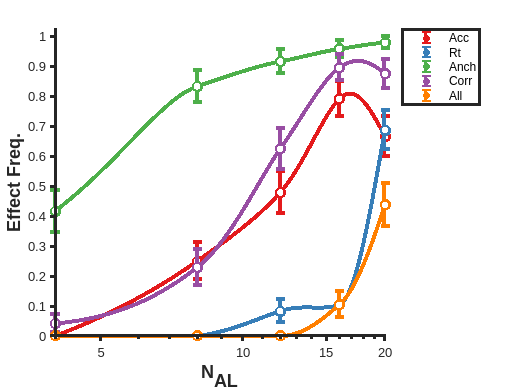

colors = brewermap(5,'Set1');
voc = 'A':'Z';

figure
hold on

ndx = find(condition1);

interp_mode = "makima";
Ns = TN.N_AL(1:end);
f = griddedInterpolant(Ns,T.MBA(1:end),interp_mode);
x = Ns(1):0.05:Ns(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBA(1:end), T.StdMBA(1:end)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(Ns, T.MBA(1:end),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(Ns,T.MBRt(1:end),interp_mode);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBRt(1:end), T.StdMBRt(1:end)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(Ns, T.MBRt(1:end),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(Ns,T.MBANC(1:end),interp_mode);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBANC(1:end), T.StdMBANC(1:end)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(Ns, T.MBANC(1:end),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(Ns,T.MBCorr(1:end),interp_mode);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBCorr(1:end), T.StdMBCorr(1:end)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(Ns, T.MBCorr(1:end),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(Ns,T.MBAll(1:end),interp_mode);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBAll(1:end), T.StdMBAll(1:end)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(Ns, T.MBAll(1:end),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

set(gca, 'XScale', 'log')
legend('Location','bestoutside')

ylim([0 1.025])
xlabel('N_{AL}',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')